# **DSP Lab 7**

## **Syed Asghar Abbas Zaidi and Samiya Ali Zaidi**

### **Spring 2024**

## **Task 1 Warm Up Question **

### **Solve the following Convolution Problem. Let **$X_1 \left(z\right)=2+3z^{-1} +4z^{-2}$ and $X_2 \left(z\right)=3+4z^{-1} +5z^{-2} +6z^{-3}$. Determine $X_3 \left(z\right)=X_1 \left(z\right)X_2 \left(z\right)$

### Answer: 

#### 
$$\begin{array}{l}
\Rightarrow \left(z+3z^{-1} +4z^{-1} \right)\left(3+4z^{-1} +5z^{-2} +6z^{-3} \right)\\
\Rightarrow \left(6+8z^{-1} +10z^{-2} +12z^{-3} \right)+\left(9z^{-1} +12z^{-2} +15z^{-3} +18z^{-4} \right)+\left(12z^{-2} +16z^{-3} +20z^{-4} +24z^{-5} \right)\\
\Rightarrow 6+17z^{-1} +34z^{-2} +43z^{-3} +38z^{-4} +24z^{-5} 
\end{array}$$


## **Task 2 Given a causal system determine H(z) and sketch its pole-zero plot**


$$H\left(z\right)=\frac{1}{\;1-0\ldotp 9z^{-1} };|z|>0\ldotp 9$$


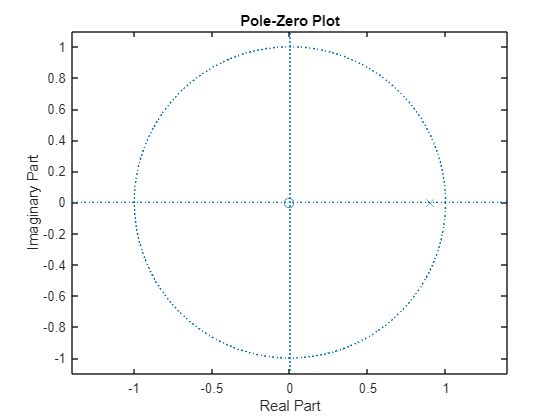

b = [1,0];
a = [1,-0.9];
zplane(b,a);

### Questions

### a) What does a and b and a represent 

 **b** represents the numerator which represents the zeros. **a **represents the denominator and represents the poles.

### b) Is system casual, Explain the reason

System can be causal because all the poles are inside the **unit circle**

## **Task 2: Part(b)**

#### 
$$\begin{array}{l}
\frac{Y\left(z\right)}{X\left(z\right)}=\frac{z+1}{z^2 -0\ldotp 9z+0\ldotp 81}\\
\Rightarrow \left(\frac{z+1}{z^2 -0\ldotp 9z+0\ldotp 81}\right)*\left(\frac{z^{-2} }{z^{-2} }\right)\\
\Rightarrow \frac{z^{-1} +z^{-2} }{1-0\ldotp 9z^{-1} +0\ldotp 81z^{-2} }
\end{array}$$


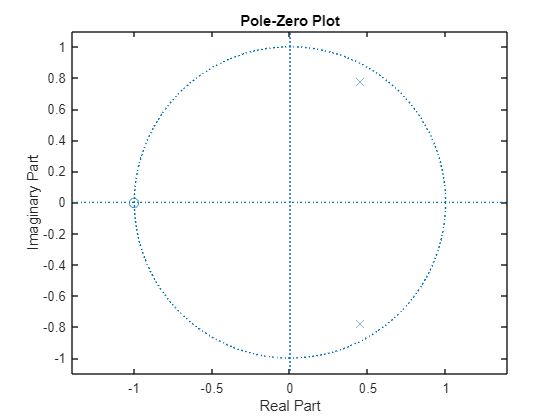

Zeroz = [0, 1, 1];
Polez = [1,-0.9,0.81];
zplane(Zeroz,Polez);

## **Task 3 Using residue command solve the rational Z transform **

### **Warm-up Question**

### To check our residue calculations, let us consider the rational function


$$X\left(z\right)=\frac{z}{3z^{2\;} -4z+1}$$


b = [0,1];
a = [3,-4,1];
[R,p,C] = residuez (b,a);
str_Task3_a_Zeros = ['The Zeros of Task 3(a) are: ' num2str(R')]; disp(str_Task3_a_Zeros);

The Zeros of Task 3(a) are: 0.5        -0.5


str_Task3_a_Poles = ['The Poles of Task 3(a) are: ' num2str(p')]; disp(str_Task3_a_Poles);

The Poles of Task 3(a) are: 1     0.33333


### Similarly, to convert back to the rational function form

[b,a] = residuez(R,p,C)

b =    -0.0000    0.3333


a =     1.0000   -1.3333    0.3333


This can be written as: 


$$X\left(z\right)=\frac{0+\frac{z^{-1} }{3}}{1-\frac{4}{3}z^{-1} +{\frac{z}{3}}^{-2} }=\frac{z}{3z^2 -4z+1}$$


## **Question 1: Analyzing results obtained from residue Matlab Command **


$$X\left(z\right)=\frac{z}{5z^{3\;} +0z^{-2} -4z+1}$$


Zeroz = [0,1];
Polez = [5,0,-4,1];

### What is the value of R and P

[R,p,C] = residuez (Zeroz,Polez)  

R =    -0.0909
    0.1877
   -0.0968


p =    -1.0000
    0.7236
    0.2764



C =

     []



**Referring from above: **


$$\frac{0\ldotp 0909}{1-z^{-1} }+\frac{0\ldotp 1877}{1-0\ldotp 7236z^{-1} }-\frac{0\ldotp 0968}{1-0\ldotp 2764z^{-1} }$$


### What is C. What does it represent? 

Direct terms of partial fraction are represented by C.

**The C is [ ] : **C represents constant which doesn't exist here.

### Write down the equation using value of R (Zeros) and P (Poles)?

[Zeros,Polez] = residuez(R,p,C)

Zeros =    -0.0000    0.2000    0.0000


Polez =     1.0000    0.0000   -0.8000    0.2000


### Converting back to the rational function form


$$X\left(z\right)=\frac{-0+0\ldotp 2z^{-1} +0z^{-2} }{1+0z^{-1} -0\ldotp 8z^{-2} +0\ldotp 2z^{-3} }=\frac{\;{0\ldotp 2z}^{-1} }{1-0\ldotp 8z^{-2} +0\ldotp 2z^{-3} }$$
 

### **Question 2:**

#### **Given a stable system with z-transform; **$H\left(z\right)=\;\frac{1}{\left(1-0\ldotp 25z^{-1} \right){\left(1-0\ldotp 5z^{-1} \right)}^2 }$

#### find the inverse transform h[n]:


$$\begin{array}{l}
H\left(z\right)=\frac{1}{{\left(1-0\ldotp 9z^{-1} \right)}^2 \left(1+0\ldotp 9z^{-1} \right)}\\
\frac{A}{1+0\ldotp 9z^{-1} }+\frac{B}{1-0\ldotp 9z^{-1} }+\frac{C}{\left(1-0\ldotp 9z^{-1} {\left.\right)}^2 \right.}\\
={A\left(1-0\ldotp 9z^{-1} \right)}^2 +B\left(1-0\ldotp 9z^{-1} \right)\left(1+0\ldotp 9z^{-1} \right)+C\left(1+0\ldotp 9z^{-1} \right)
\end{array}$$


**For A: **$z^{-1} =\frac{-1}{0\ldotp 9}$


$$4A=1\Rightarrow A=0\ldotp 25$$


**For C: **$z^{-1} =\frac{1}{0\ldotp 9}$


$$1=2C\Rightarrow C=0\ldotp 5$$


**Using Differentiation**


$$0=-0\ldotp 9A\left(1-0\ldotp 9z^{-1} \right)-0\ldotp 81B+0\ldotp 9C$$


**Set **$z^{-1\;} =\frac{1}{0\ldotp 9}$


$$\begin{array}{l}
0=-0\ldotp 81B+0\ldotp 9\left(0\ldotp 5\right)\\
B=\frac{5}{9}\\
\frac{0\ldotp 25}{1+0\ldotp 9z^{-1} }+\frac{5}{9\left(1-0\ldotp 9z^{-1} \right)}+\frac{0\ldotp 5}{{\left(1-0\ldotp 9z^{-1} \right)}^2 }
\end{array}$$


### 
$$x\left\lbrack n\right\rbrack =-{\left(-0\ldotp 9\right)}^n u\left(-n-1\right)\left(0\ldotp 25\right)+\frac{5}{9}0\ldotp 9^n u\left\lbrack n\right\rbrack$$


syms z n
exp = (1/(1-0.25*(z^-1))*(1-0.5*(z^-1))^2);
disp(exp);

$$-\frac{{\left(\frac{1}{2\,z}-1\right)}^{2}}{\frac{1}{4\,z}-1}$$

#### **D.1 Resolving Partial Fractions **

% Use the poly command to obtain the polynomial coefficients from its roots
poly1 = poly([0.25 0.5 0.5])

poly1 =     1.0000   -1.2500    0.5000   -0.0625


#### Equation: 

We can infer that we got, $f\left(x\right)=x^3 -1\ldotp 25x^2 +0\ldotp 5x-0\ldotp 0625$

Thus, we got


$$H\left(z\right)=\frac{1}{-0\ldotp 0625+0\ldotp 5z^{-1} -1\ldotp 25z^{-2} +z^{-3} }$$


% For extra info, we will use the roots commond to obtain the roots of the polnomial.
roots1 = roots([1 -1.25 0.5 -0.0625]); %This will give us back 0.5 0.5 0.25 which is to be expected

## **Task-4 (D3) **

#### Note: sir asked to use the following fraction for this part instead of the one written in the manual

#### $H(z) = \frac{1- 4z^{-1} + 8z^{-2}}{1- 2.5z^{-1} + z^{-2}}$:

#### To convert this irrational fraction into a rational fraction, long division operation was performed. And then using partial fraction expansion, the ROC was determined:

#### 
$$H\left(z\right)=\frac{1-4z^{-1} +8z^{-2} }{1-\frac{3}{2}z^{-1} +z^{-2} }$$


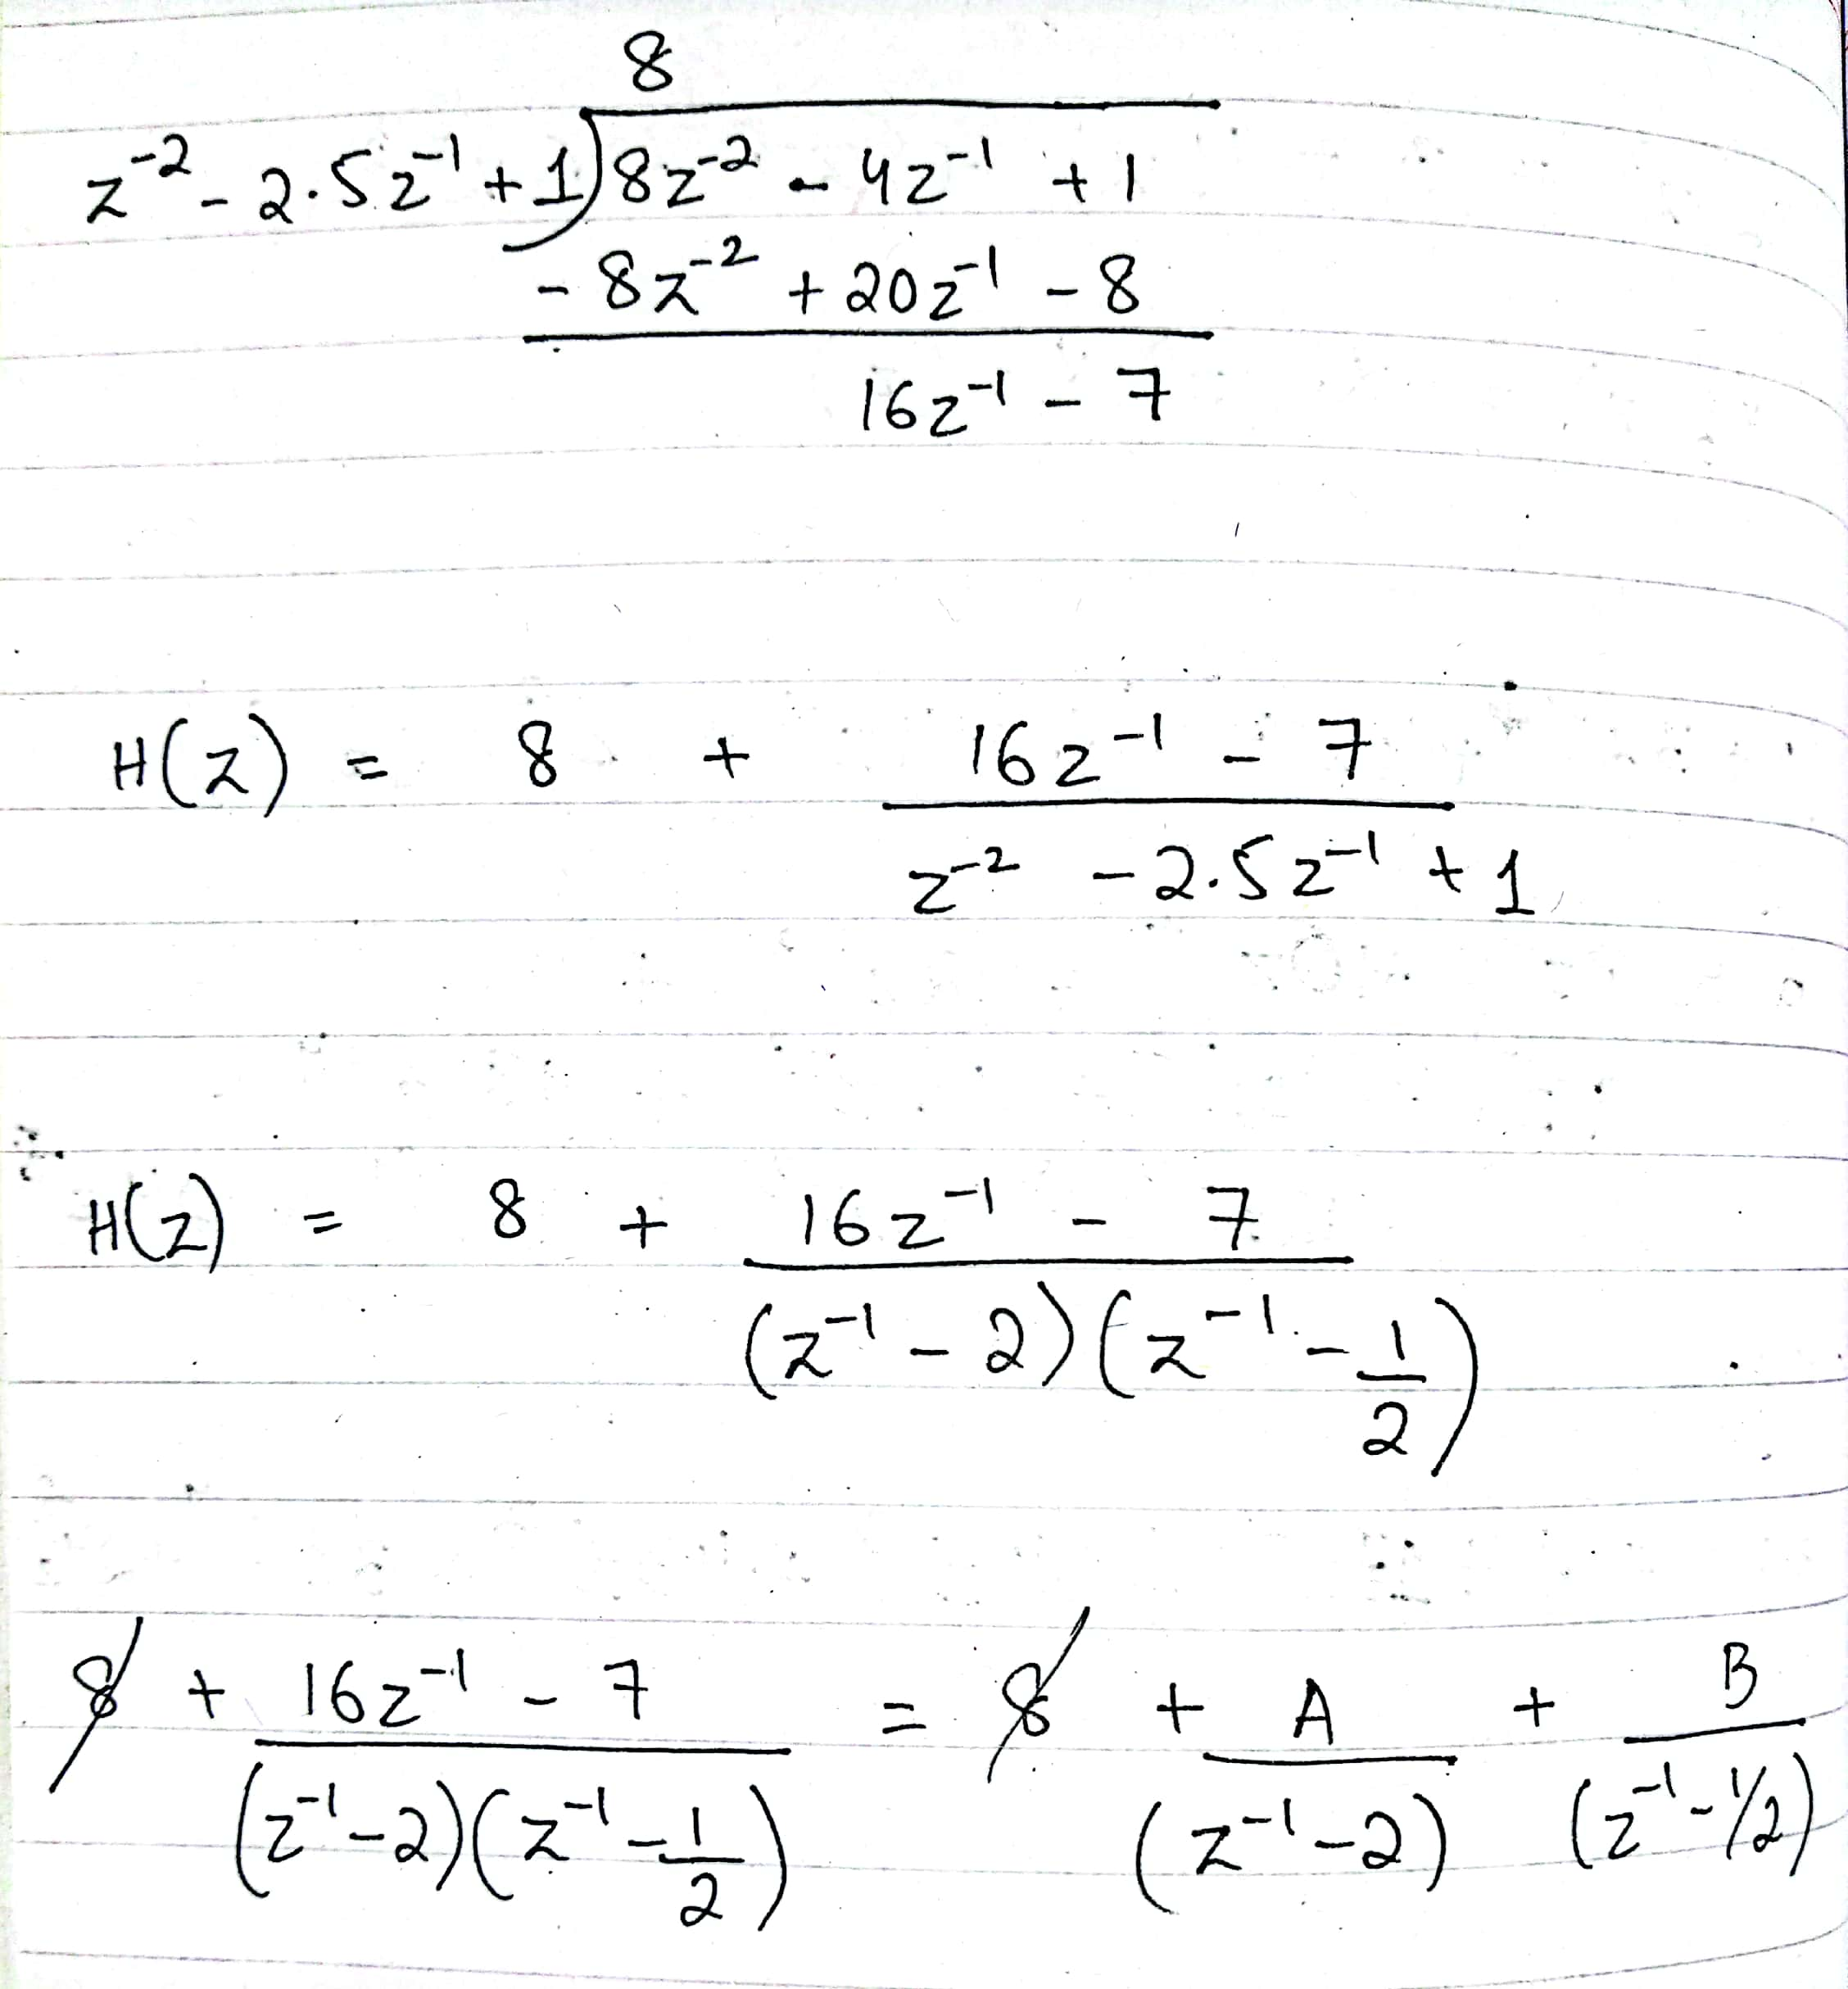 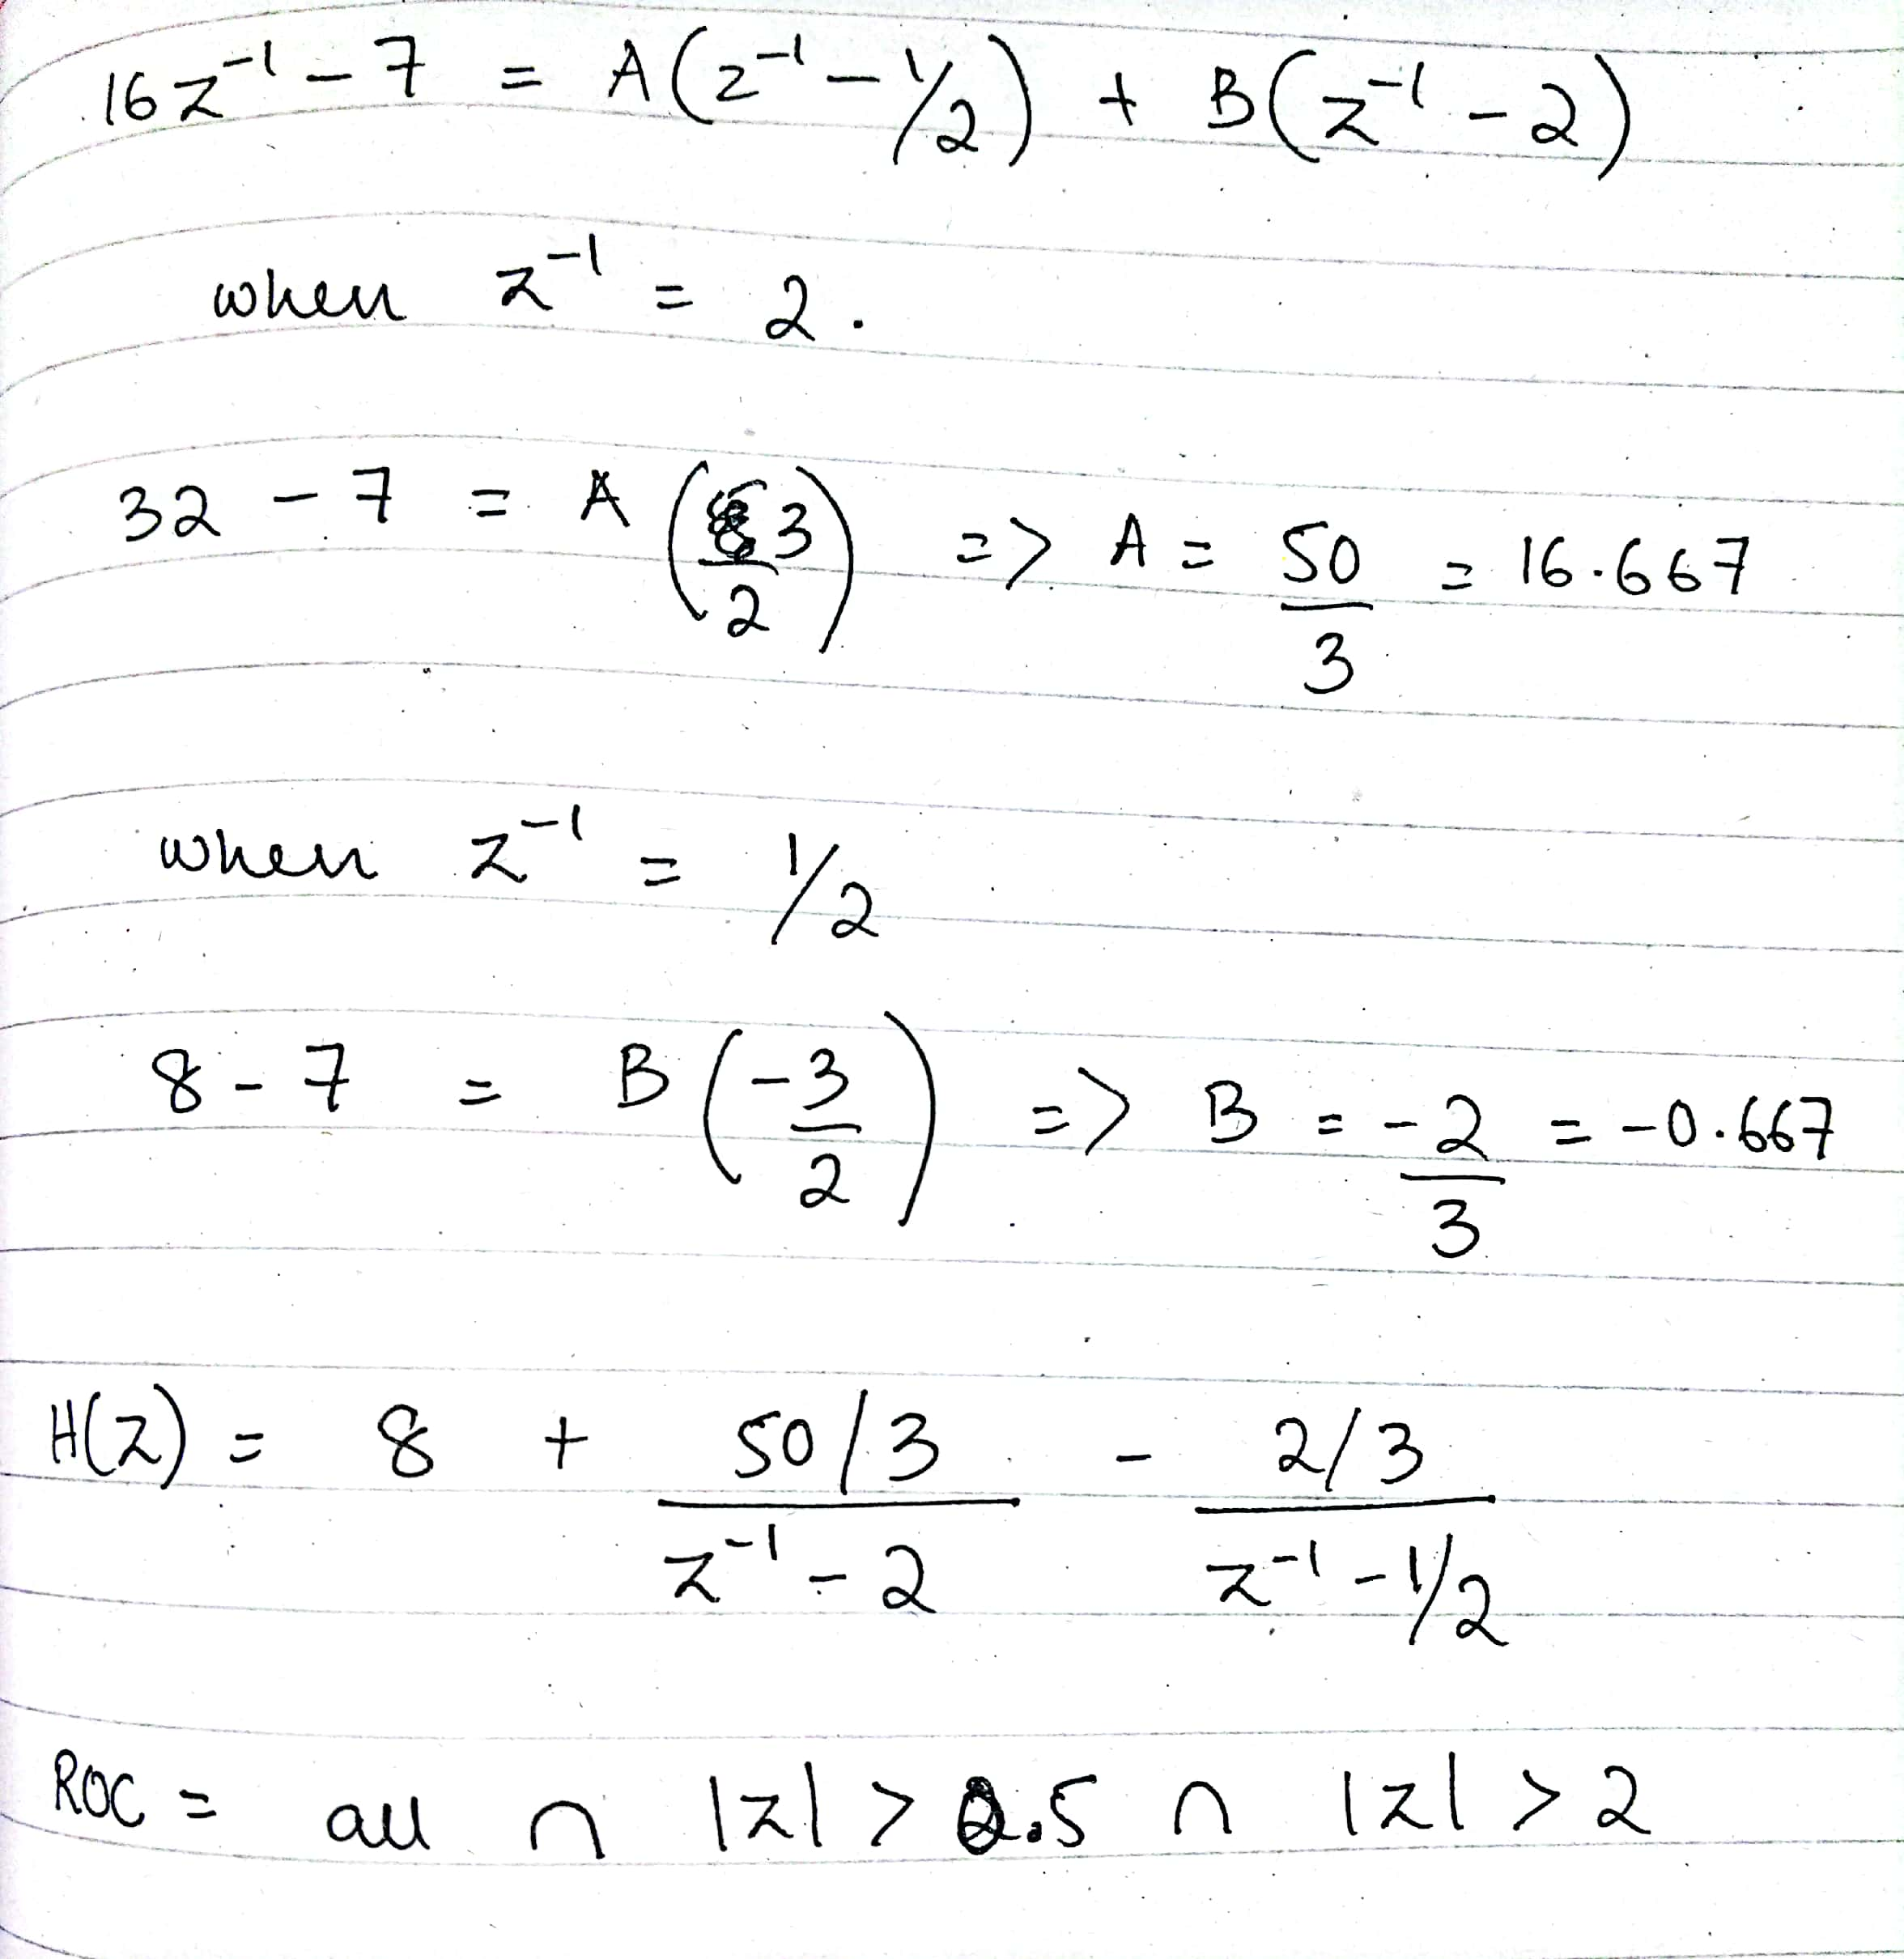

### **D.2**

**Verifying this part using matlab.**


$$H\left(z\right)=\frac{1+0\ldotp 4z^{-1} -2\ldotp 2z^{-2} +0\ldotp {8z}^{-3} }{\;1-1\ldotp 3z^{-1} +0\ldotp 4^{-2} }$$


% Define the numerator and denominator coefficients of the "transfer
% function"
B = [1, 0.4, -2.2, 0.8];
A = [1, -1.3, 0.4];

% Compute the partial fraction decomposition
[R, p, C] = residuez(B,A)

R =    -1.0000
    1.0000


p =     0.8000
    0.5000


C =      1     2


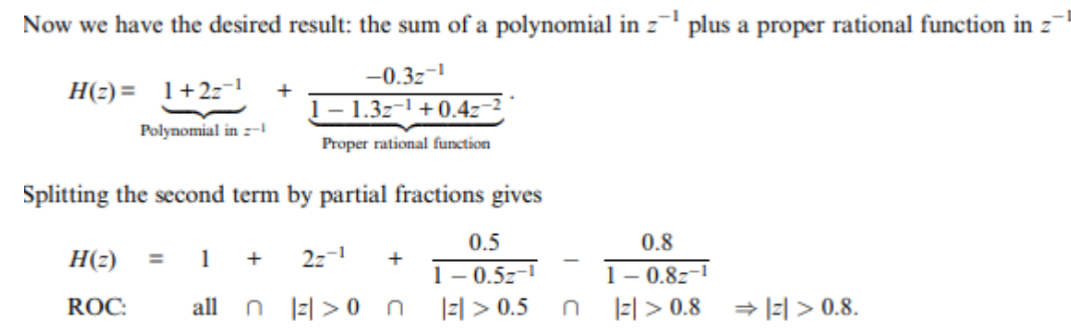

**Analysis: **

As can be observed, in **C,** we are getting direct polynomial terms aka 1 and 2, which don't contribute to poles in the partial fraction decomposition. So they are similar. 

**P** have 0.5 and 0.8, and as can be referred from "D2", we are getting teh same poles that contribute to ROC!

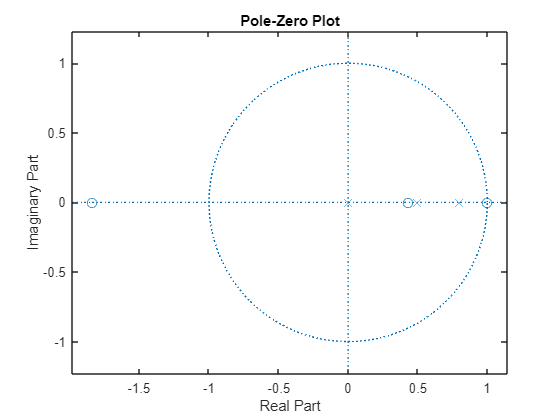

%Plotting the poles and zeros
zplane(B,A);

#### Solving for D3, whch is (same question in which we did the long division)


$$H\left(z\right)=\frac{1-4z^{-1} -8z^{-2} }{\;1-2\ldotp 5z^{-1} +z^{-2} }$$


% Define the numerator and denominator coefficients of the transfer function
B = [1, -4, 8];
A = [1, -2.5, 1];

% Compute the partial fraction decomposition
[R, p, C] = residuez(B,A)

R =     1.3333
   -8.3333


p =     2.0000
    0.5000


C = 8

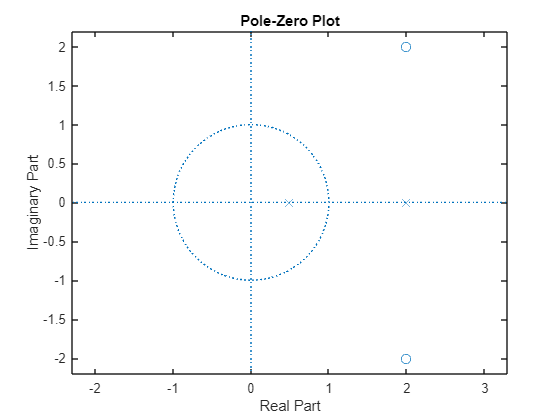

zplane(B,A);